k=3;
n=2^k;
x=0:1/n:1;
f=(@(x)sqrt(x));
GroundTruth=integral(f,0,1)

GroundTruth = 0.6667

fure=FuHeTiXing(f, k)

Result = 0.6581

fure = 0.6581

fuxi=FuHeiXingPuSheng(f,k)

Result = 0.6654

fuxi = 0.6654

FuHeTiXingResultBias=zeros(8,1);

FuHeTiXingResultBias=zeros(8,1);
FuHeiXingPuShengResultBias=zeros(8,1);
for k=3:10
    FuHeTiXingResult=FuHeTiXing(f, k);
    FuHeTiXingResultBias(k-2)=abs(GroundTruth-FuHeTiXingResult);
    FuHeiXingPuShengResult=FuHeiXingPuSheng(f,k);
    FuHeiXingPuShengResultBias(k-2)=abs(GroundTruth-FuHeiXingPuShengResult);
end
    

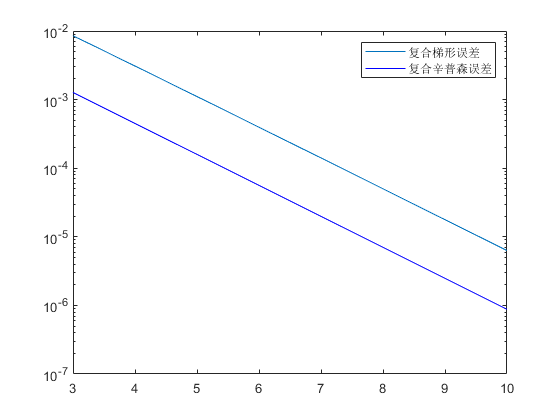

semilogy(3:10,FuHeTiXingResultBias,3:10,FuHeiXingPuShengResultBias,'b-')
legend('复合梯形误差','复合辛普森误差')

function Result=FuHeiXingPuSheng(f,k)
n=2^k;
h=1/n;
x=0:h:1;
Result=(h/6)*(f(x(1))+2*sum(f(x(2:end-1)))+4*sum(f(x(1:end-1)+h/2))+f(x(end)));
end

function Result=FuHeTiXing(f,k)
n=2^k;
h=1/n;
x=0:h:1;
Result=(h/2)*(f(x(1))+2*sum(f(x(2:end-1)))+f(x(end)));
end
